clear all

t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

knots = 4

knots = 4

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+0.3*rand(timesteps,1));
output2= cos(5*t)+0.4*rand(timesteps,1)

output2 =     1.3100
    1.3346
    1.1906
    0.8499
    0.6010
    0.6545
    0.3847
   -0.0699
   -0.3250
   -0.4998



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -1.0057
   -1.2785
   -1.2997
   -1.2287
   -1.2999
   -0.9916
   -0.3918
   -0.2347
   -0.1872
   -0.0850


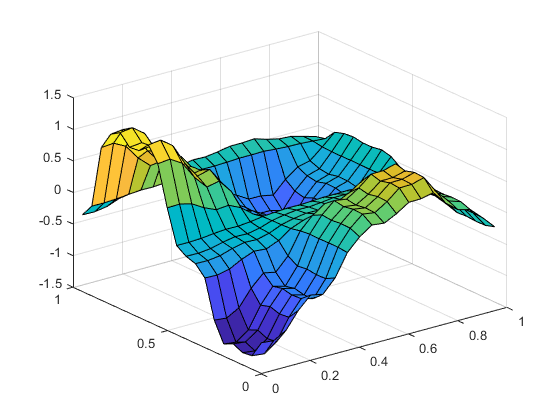


% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));
   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros(36,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye(36)*1000

Pcov =         1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0        1000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0        1000           0           0           0           0           0           0           0       



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsil = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsil;

end
toc

Elapsed time is 0.146375 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:) ;
toc

Elapsed time is 0.009620 seconds.


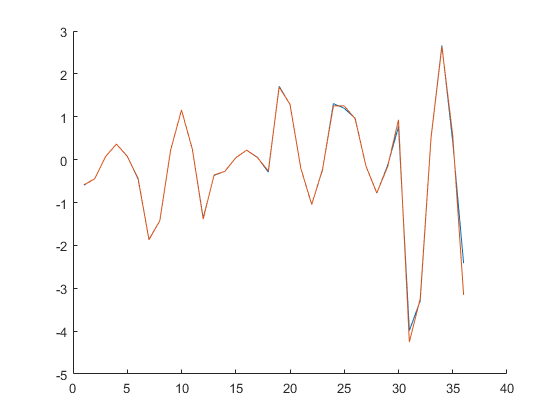


y=C*P;
y=C*Theta;

figure;
hold on
plot(Theta)
plot(P)
hold off

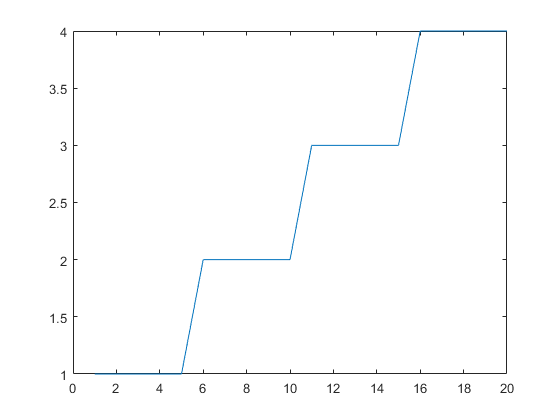


plot(index)

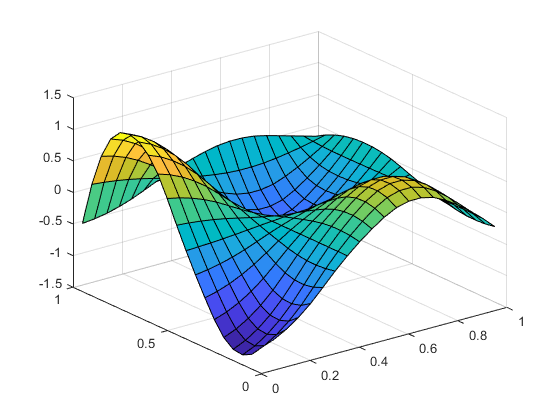

surf(t,t,reshape(y,[timesteps timesteps]))

surf(t,t,output_curve)

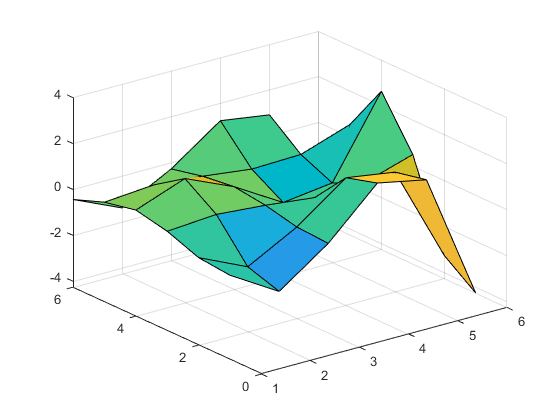


surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))


norm(reshape(y,[timesteps timesteps])-output_curve)

ans = 1.7870


% surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))



[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

coeff =     0.1141    0.8879   -0.0865   -0.4273    0.0863
    0.3629   -0.1919    0.7487   -0.3785    0.3549
    0.0694   -0.0163    0.1626   -0.2253   -0.5708
   -0.3285    0.3591    0.6319    0.4827   -0.3106
   -0.2433    0.1517    0.0416    0.3275    0.6649
    0.8267    0.1504   -0.0670    0.5322   -0.0475


score =    -3.7453    0.0000   -0.0000   -0.0000   -0.0000
   -2.5277   -0.0000    0.0000   -0.0000    0.0000
    2.0217    0.0000   -0.0000    0.0000    0.0000
    4.5898   -0.0000   -0.0000   -0.0000   -0.0000
    2.0792    0.0000    0.0000    0.0000   -0.0000
   -2.4176   -0.0000   -0.0000    0.0000   -0.0000


latent =    11.1474
    0.0000
    0.0000
    0.0000
    0.0000


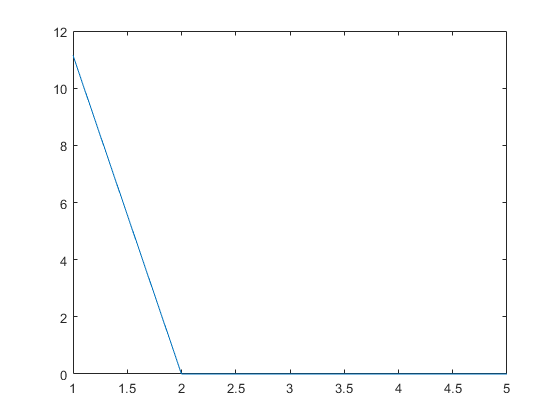


plot(latent)